# EXERCISE #2 : Build and simulate a Bluetooth LE wireless sensor network model

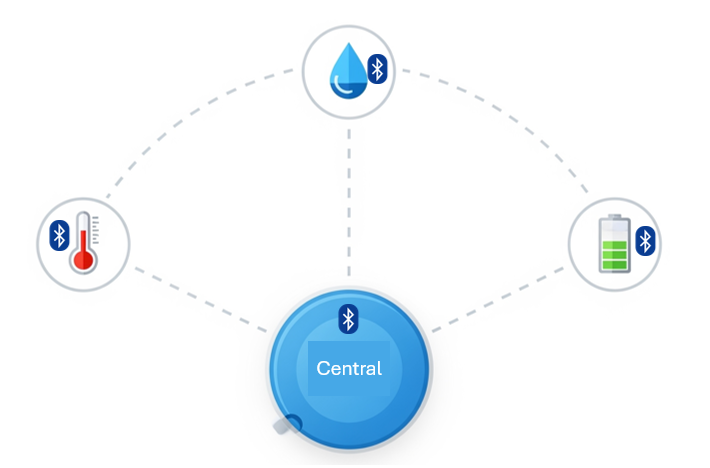

Bluetooth LE Piconet 

**In this exercise, you will:**

- Establish and configure a asynchronous connection-oriented logical Transport (ACL) between the Central and Peripheral nodes.

- Model a bluetooth sensor network 

- Measure key performance indicators (KPIs) such as throughput.

- Collect performance statistics for both the Central and Peripheral nodes.

rng(1,"twister");
wirelessnetworkSupportPackageCheck
p = addpath(fullfile('.', 'Shared', 'Helpers'), fullfile('.', 'Shared', 'Utilities')); % Add path to helpers and utilities
all_figs = findall(0, 'type', 'figure');close(all_figs); % close all previous windows
simulationTime = 0.5;
networkSimulator = wirelessNetworkSimulator.init;

Create a Bluetooth LE node, specifying the role as `"central"`. Specify the name and position of the node.

centralNode = bluetoothLENode("central", ...
    "Name","CN", ...
    Position=[0 0 0], ...
    TransmitterPower=-20, ...
    TransmitterGain=0, ...
    ReceiverGain=0, ...
    ReceiverSensitivity=-100);

Create a Bluetooth LE node, specifying the role as `"peripheral"`. Specify the name and position of the node. You can create multiple Bluetooth nodes with a single function call.

peripheralNode = bluetoothLENode("peripheral", ...
    Position=[0 1 0; 2 1 2;1 1 0], ...
    Name=["PN-1", "PN-2","PN-3"], ...
    TransmitterPower=-20, ...
    TransmitterGain=0, ...
    ReceiverGain=0, ...
    ReceiverSensitivity=-100);

# Task #1/3 Create ACL connection between the central and peripheral 

A connection event in Bluetooth Low Energy (BLE) is the fundamental time interval during which the central and peripheral exchange data once a connection is established.

In BLE, the active period is the portion of a connection event during which:

- The central transmits

- The peripheral responds

- They exchange 1 or more packets

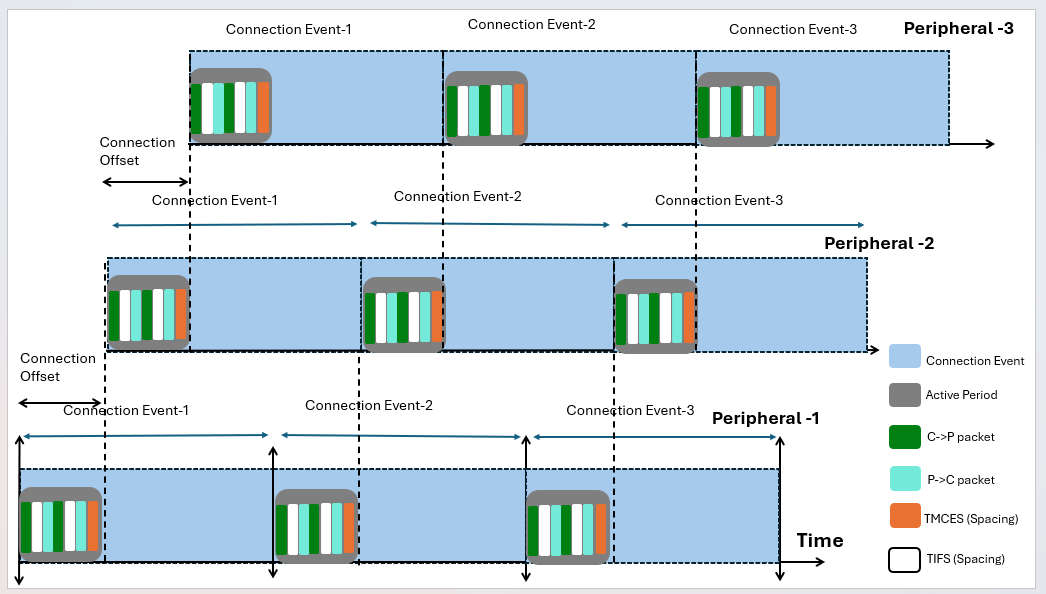

connectionInterval = 0.075; % Time in secs between the start of two consecutive connection events on the same ACL link.
activePeriod = 0.005; % Active communication period in secs in each connection event
tifs = 150e-6; % Interframe space in secs
tmces = 150e-6; % Minimum time interval in secs between the last PDU that the Peripheral node transmits and the anchor point of the next connection event
connectionOffset = [0,0.025,0.050]; 
accessAddress = ["5DA44270","5DA44271","5DA44272"];

algorithm = 1; % Algorithm, specified as 1 or 2 representing "Algorithm #1" or "Algorithm #2
hopIncrement = 5; % Specifies the number of hops between data channels
maxPDU = 251; % Maximum number of data octets that a data protocol data unit (PDU) can carry 
phyMode = "LE1M"; % PHY mode, specified as "LE1M", "LE2M", "LE125K", or "LE500K"
bleMinActivePeriod(maxPDU, phyMode) % This function prints the minimum active period required for a valid ACL connection  

% Use bluetoothLEConnectionConfig() function to configure the ACL connection 
% Write configuration in a variable named "cfgConnection"
% Hint: Type "doc bluetoothLEConnectionConfig" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% PHYMode = phyMode
% ConnectionInterval=connectionInterval 
% ActivePeriod=activePeriod
% MaxPDU=maxPDU
% Algorithm=algorithm
% HopIncrement=hopIncrement

% Write code here
% cfgConnection = 

% Establish connection between central node and each peripheral node
for i = 1:length(peripheralNode)
    cfgConnection.ConnectionOffset = connectionOffset(i);
    cfgConnection.AccessAddress = accessAddress(i);
    cfgConnection.HopIncrement = i*5;
    configureConnection(cfgConnection, centralNode, peripheralNode(i));
end

# Task #2/3 Configure a traffic model 

Application Traffic Pattern Modeling

- On-Off Traffic (Periodic, Bursty, or Random) – Represents intermittent data transmission patterns with varying activity periods.

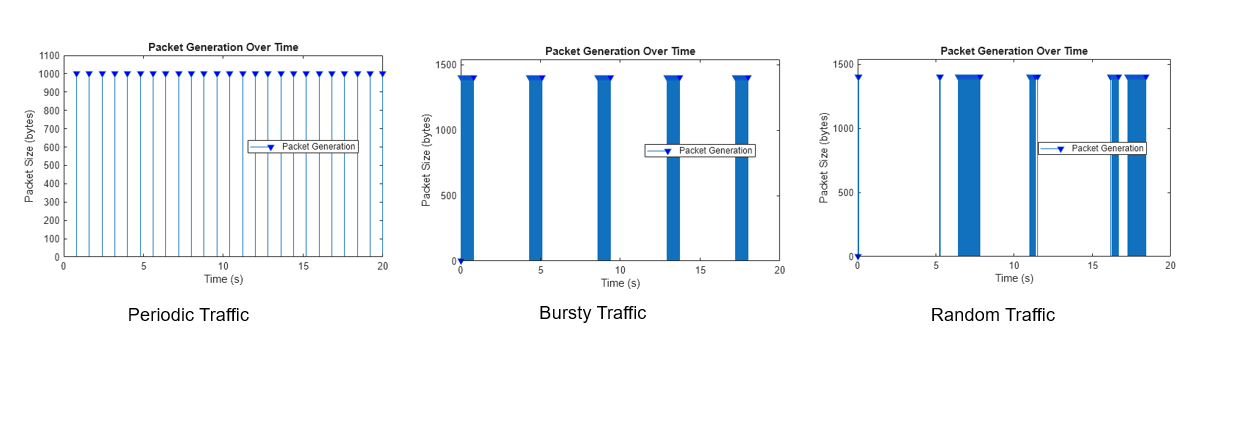

Other supported application trafiic models 

- Full-Buffer Traffic – Represents constant data transmission with an always-full buffer.

- FTP (File Transfer Protocol) – Models file-based data transfer sessions.

- Video Streaming – Simulates continuous media flow with variable bit rates.

- Voice over IP (VoIP) – Models real-time voice communication traffic.

dataRate = 250; % in kbps
ontime = inf;
offtime = 0;

% Define traffic type
% Use networkTrafficOnOff() function to configure application layer traffic
% Write configuration in a variable named "traffic"
% Hint: Type "doc networkTrafficOnOff" in the MATLAB Command Window, and see the "Syntax" section.
% Note : use the following values to start with
% onTime = ontime
% OffTime = offtime
% DataRate = dataRate % in kpbs
% PacketSize = maxPDU
% GeneratePacket=true

  % <enter code below>
% traffic = 

plotTrafficPattern(simulationTime,traffic)

#### Add traffic from Central to Peripheral

trafficFromCentralToPeripheral = false;
if trafficFromCentralToPeripheral
    for i = 1:length(peripheralNode)
        traffic= networkTrafficOnOff(DataRate=dataRate,PacketSize=maxPDU,GeneratePacket=true,OnTime=ontime,OffTime=offtime);
        addTrafficSource(centralNode,traffic,"DestinationNode",peripheralNode(i));
    end
end

#### Add traffic from Peripheral to Central

trafficFromPeripheralToCentral = false;
if trafficFromPeripheralToCentral
    for i = 1:length(peripheralNode)
        traffic= networkTrafficOnOff(DataRate=dataRate,PacketSize=maxPDU,GeneratePacket=true,OnTime=ontime,OffTime=offtime);
        addTrafficSource(peripheralNode(i),traffic,"DestinationNode",centralNode);
    end
end


#### Add the Central and Peripheral nodes to the wireless network simulator.

nodes = [centralNode peripheralNode];
addNodes(networkSimulator,nodes);

#### Configure WLAN Signal Interference 

- One network reacting to interference 

- Networks interfering and reacting to each other (non-collaborative) 

- Collaborative coexistence

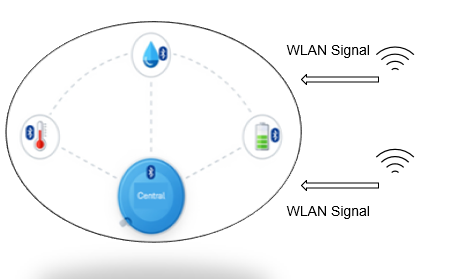

enableWLANInterference = false;
if enableWLANInterference
    wlanInterferenceSource = "BasebandFile";
    numWLANNodes = 2;                                           % Two WLAN interferers
    wlanNodePositions = [4 4 0; 5 5 0];                         % x-, y-, and z-coordinates in meters
    wlanCenterFrequency =  [2.412e9; 2.442e9];                  % Center frequency (in Hz) based on the channel of operation
    wlanNodes = helperInterferingWLANNode.empty(0,numWLANNodes);
    for wlanIdx=1:numWLANNodes
        wlanNodeObj = helperInterferingWLANNode(...
            WaveformSource=wlanInterferenceSource, ...
            Position=wlanNodePositions(wlanIdx,:), ...
            Name="WLAN node", ...
            TransmitterPower=15, ...                            % In dBm
            CenterFrequency=wlanCenterFrequency(wlanIdx), ...
            Bandwidth = 20e6, ...                               % In Hz
            SignalPeriodicity=0.0029);                          % In seconds
        wlanNodes(wlanIdx) = wlanNodeObj;
    end
    addNodes(networkSimulator,wlanNodes);
end

#### Add the custom channel to the wireless network simulator.

addChannelModel(networkSimulator,@addImpairment);

#### Visualize Packet Transitions

helperPlotPacketTransitions(nodes,simulationTime,FrequencyPlotFlag=true);

#### Enable packet capture 

clear packetCaptureObj;
packetCaptureObj = helperPacketCapture(nodes,"pcap");

#### Set the simulation time in seconds and run the simulation.

run(networkSimulator,simulationTime)

#### Retrieve application, link layer (LL), and physical layer (PHY) statistics corresponding to the Central and Peripheral nodes. 

For more information see [Bluetooth LE Node Statistics](https://in.mathworks.com/help/bluetooth/ug/bluetooth-le-node-statistics.html).

centralStats = statistics(centralNode);
peripheralStats = statistics(peripheralNode);
centralThroughtput = (centralStats.LL(1).ReceivedBytes*8)/(simulationTime*1000);
peripheralThroughtput = (peripheralStats(1).LL.ReceivedBytes*8)/(simulationTime*1000);
fprintf('Central Rx Throughput: %f kbps\n ',centralThroughtput);
fprintf('Peripheral Rx Throughput: %f kbps\n ',peripheralThroughtput);

# Task #3/3 Measure throughput between central and peripheral-1 

% Use kpi() function to configure application layer traffic
% Write configuration in a variable named "throughput"
% Note : use the following values to start with
% centralNode
% peripheralNode(1)
% "throughput"
% Layer="LL"

[Help on measuring throughput using kpi() ](https://in.mathworks.com/help/releases/R2025a/bluetooth/ref/bluetoothnode.kpi.html)

% throughput = 

fprintf(['Throughput: %f kbps\n ' ...
    'Transmission Time: %f seconds\n ' ...
    'Listen Time: %f seconds\n ' ...
    'Sleep Time: %f seconds\n ' ...
    'Idle Time: %f seconds'], ...
    throughput, ...
    centralStats.LL(1).TransmissionTime, ...
    centralStats.LL(1).ListenTime, ...
    centralStats.LL(1).SleepTime, ...
    centralStats.LL(1).IdleTime);


delete(packetCaptureObj); 

*Copyright 2021-2023 The MathWorks, Inc.*